Feature: DH parameter + scope (x,y,z values)

resM(1,:)

ans =          0         0    0.2109    0.4579         0         0         0    0.3961    0.4797         0         0         0    1.5708         0   -1.5708    1.5708   -1.5708         0   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000         0


Target: Discretized workspace (binary vector)

resB(1,:)

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Neural network for a cross-section

section6_2_1


section6_2_1 =

    Neural Network
 
              name: 'Feed-Forward Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 5
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 212648
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1; 1; 1; 1]
      

Construting a sample for testing (PUMA560)

feature = resM(1,:)';
feature(1:18)=[0,0,0.150050000000000,0.431800000000000,0,0,0,0.431800000000000,0.0203000000000000,0,0,0,1.57079632679490,0,-1.57079632679490,1.57079632679490,-1.57079632679490,0];

Inference

tic
prediction=[section6_2_1(feature);section6_2_2(feature);section6_2_3(feature);section6_2_4(feature);section6_2_5(feature);section6_2_6(feature);section6_2_7(feature)];
disp(toc)

    2.6914



Visualization

    21

    21

    21



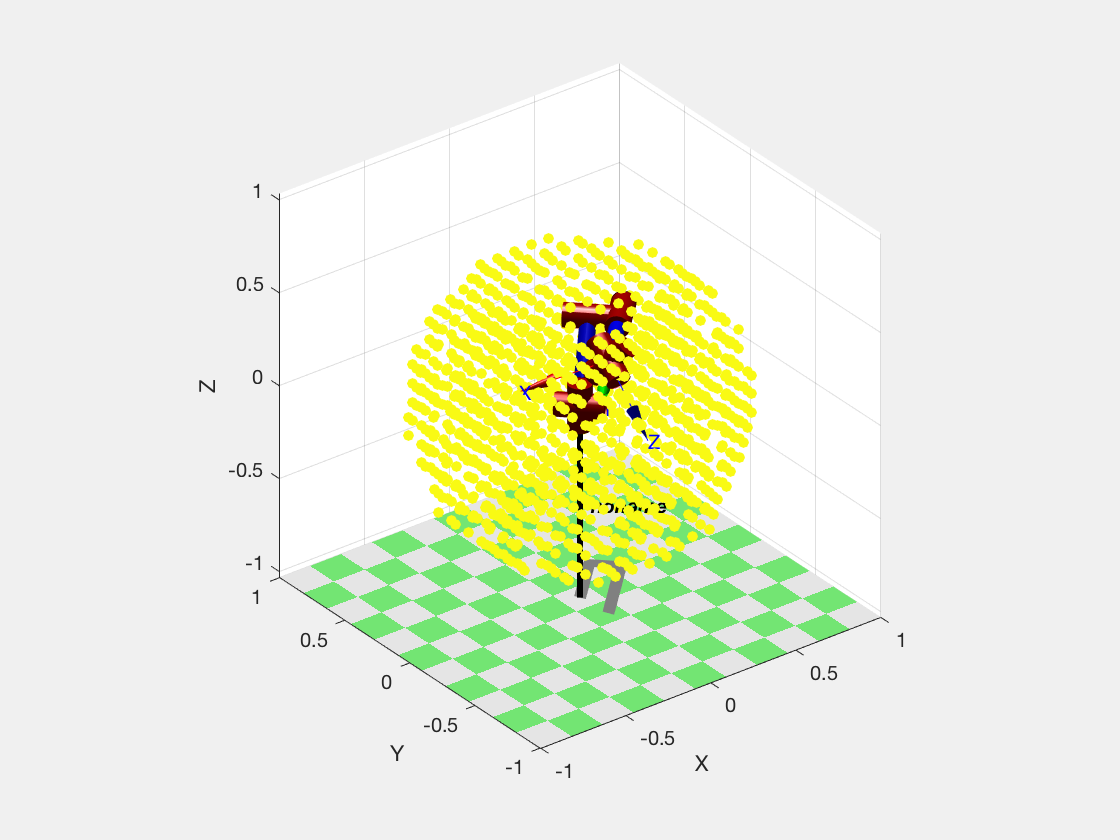

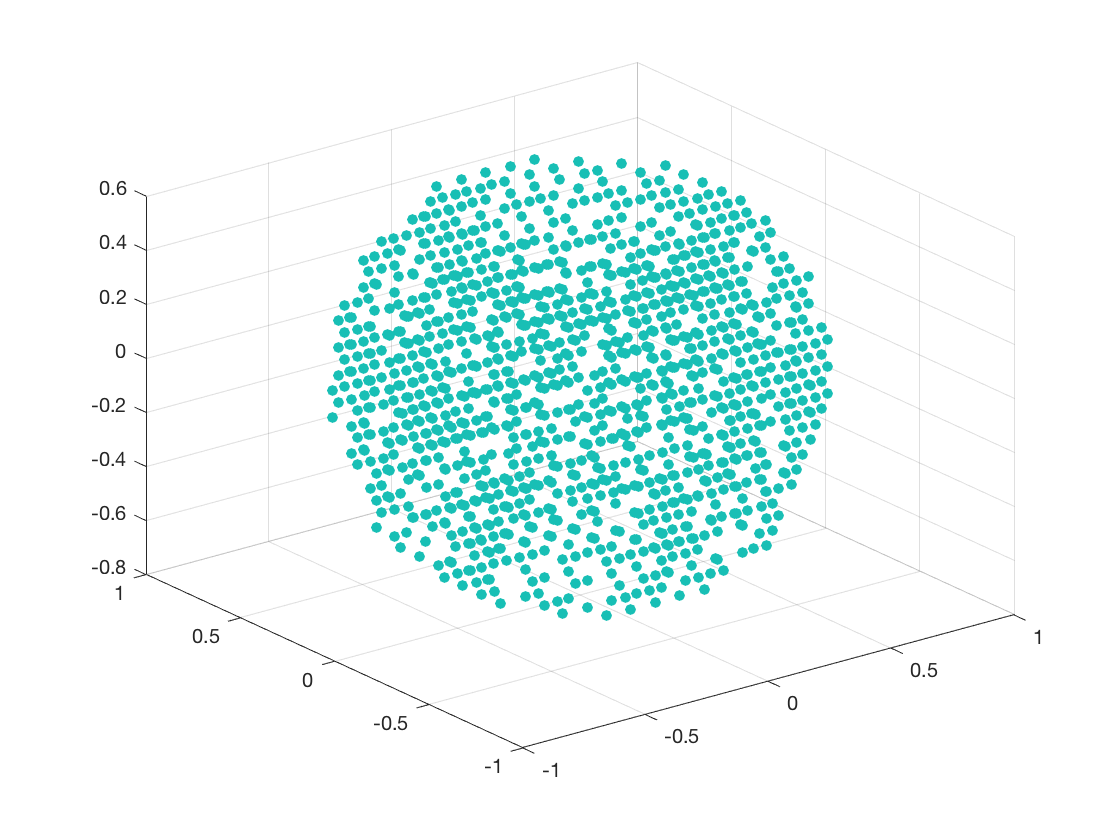

[P,delP,xData,yData,zData]=postProcessing(feature',prediction');

Raw outputs

    21

    21

    21



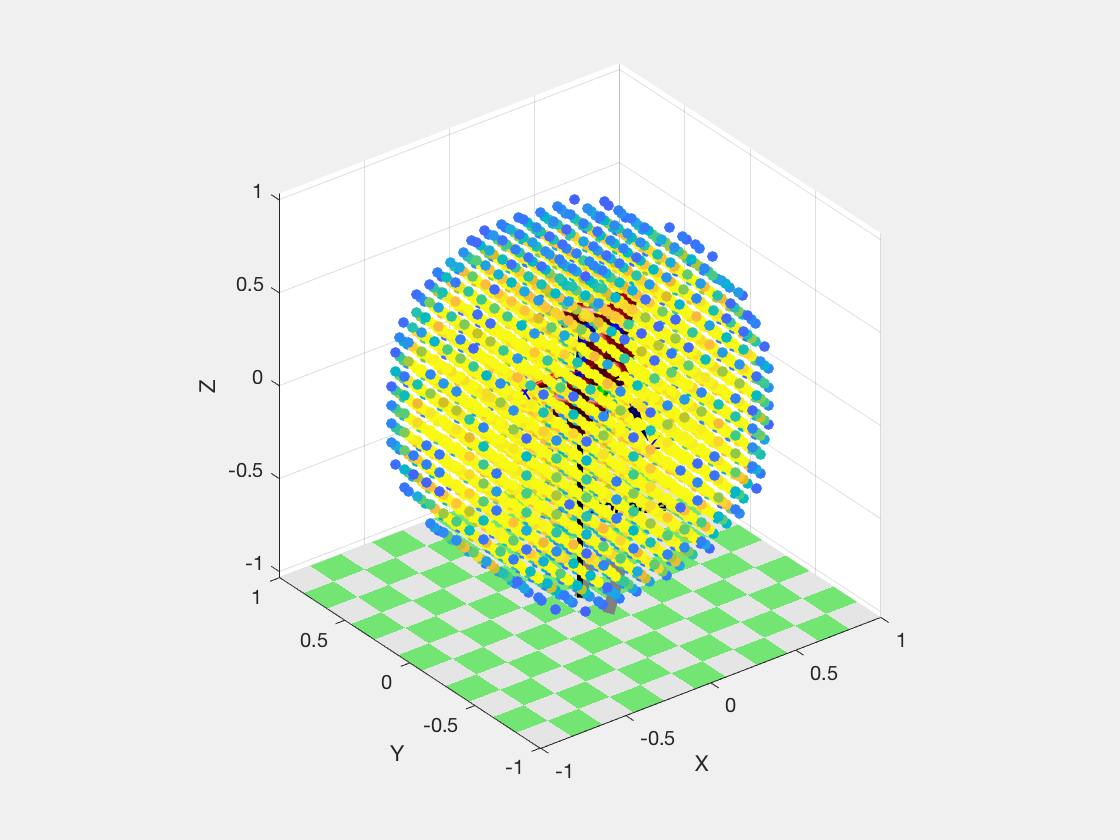

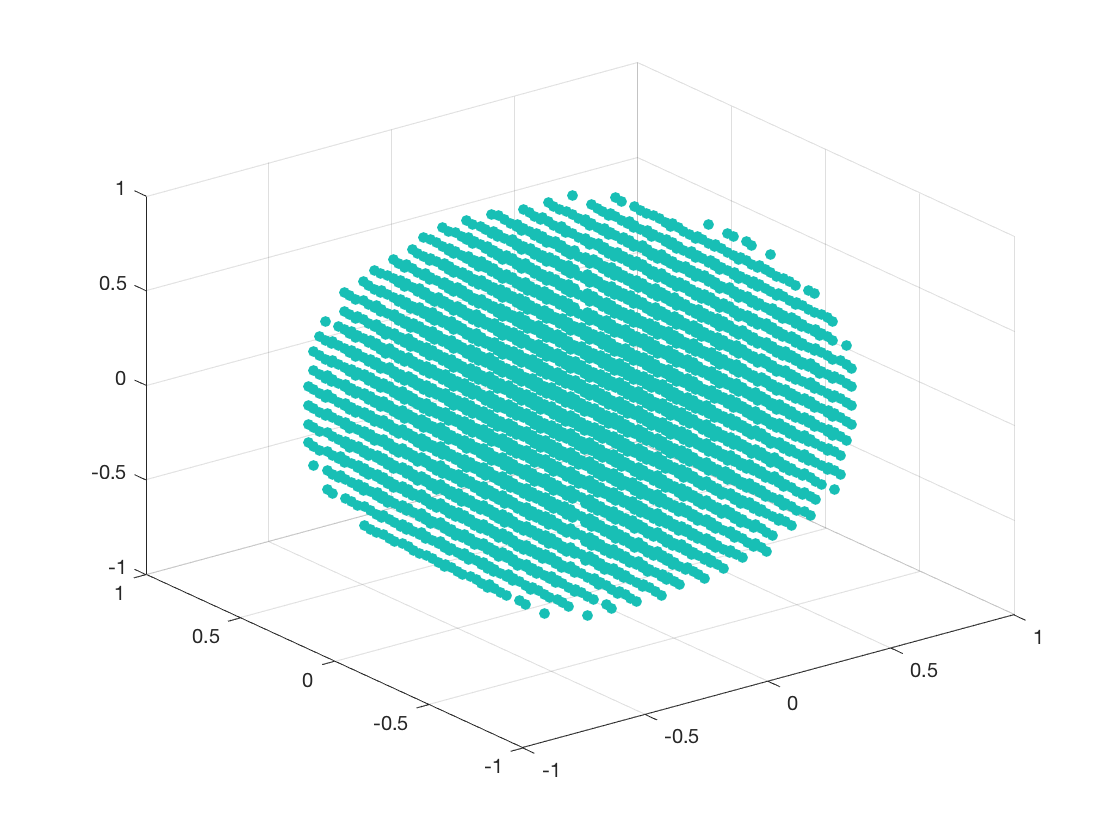

[P,delP,xData,yData,zData]=postProcessing(feature',prediction',"filter",-1,"boundary",false);

Computing F1 for a particular corss-section

predictionValidation(section6_2_1,1)

ans =     0.8726    0.8752    0.8548    0.8102    0.7613
